# Homework 2

**Name:** YOUR NAME HERE

**Due Date: **

clear, clc

## Problem #1 - Trajectory of a toy missile 

**a) Plot the equation as a function of **$\theta_0$

y0 = 1.3;
v0 = 70;
g = 3.721;
x = 290;
h = 3.4;

thetaDeg = [5,85]; 

a0 = @() y0;
a1 = @(a) tand(a);
a2 = @(a) -(g/2)./((v0.^2).*cosd(a).^2);

f = @(a) a2(a).*x.^2 + a1(a).*x + a0() - h;

figure()
fplot(f, thetaDeg)
title("HW2.1.a")
xlabel("\theta [Degrees]")
ylabel("f(\theta)")
grid on
hold on

**b) How many solutions exist?**

**     2**

**c) Table of angles that will allow the missile to hit the target**

guess_bisect_1 = bisect(f, 0, 10);
guess_bisect_2 = bisect(f, 80, 90);
guess_fzero_1 = fzero(f, 5);
guess_fzero_2 = fzero(f, 80);
fprintf("Zero #    Bisect     Fzero\n" + ...
        "------ --------- ---------\n" + ...
        "   1   %9.6f %9.6f\n" + ...
        "   2   %9.6f %9.6f\n", guess_bisect_1, guess_fzero_1, guess_bisect_2, guess_fzero_2)

Zero #    Bisect     Fzero
------ --------- ---------
   1    6.781173  6.781172
   2   83.633652 83.633721


**d) Plot the solutions from part c into the plot from part a**

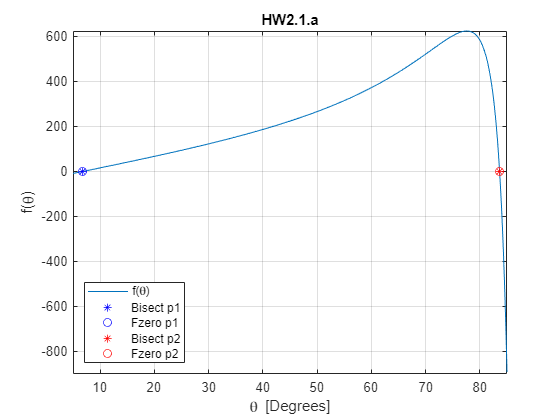

plot(guess_bisect_1, f(guess_bisect_1), "b*", guess_fzero_1, f(guess_fzero_1), "bo", ...
     guess_bisect_2, f(guess_bisect_2), "r*", guess_fzero_2, f(guess_fzero_2), "ro")
legend("f(\theta)", "Bisect p1", "Fzero p1", "Bisect p2", "Fzero p2","location", "southwest")
hold off

**e) Plot the trajectory of the toy missile**

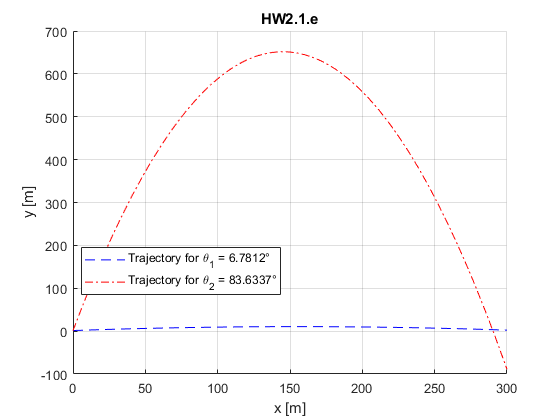

ax1 = guess_fzero_1;
fx1 = @(x) a2(ax1).*x.^2 + a1(ax1).*x + a0();
ax2 = guess_fzero_2;
fx2 = @(x) a2(ax2).*x.^2 + a1(ax2).*x + a0();

figure()
hold on
fplot(fx1, [0,300], "b--") 
fplot(fx2, [0,300], "r-.") 
grid on
title("HW2.1.e")
xlabel("x [m]")
ylabel("y [m]")
str1 = ['Trajectory for \theta_1 = ' num2str(ax1) '°'];
str2 = ['Trajectory for \theta_2 = ' num2str(ax2) '°'];
legend(str1, str2, "location", "best")

## Problem #2 - Bisect vs. False position

maxerr = .0002;
f = @(x) .074*exp(-.3*x).*sin(.1*x) + 8;

**a) Plot the function **

figure
hold on
fplot(f, [-35, -2], "b-.")
title("MAE284 HW2.2")
xlabel("X Position")
ylabel("Y Position")

**b) Compute the root.  Display the results in a table. Explain the difference**

[xrb, ib] = bisect(f, -39,-28, maxerr);
[xrfp, ifp] = falsePos(f, -39, -28, maxerr);
fprintf("Using -39 and -28 as Bounds\n\n" + ...
        "        Method           Root Iteration\n" + ...
        "-------------- -------------- ---------\n" + ...
        "        Bisect %13.10f %9d\n" + ...
        "False Position %13.10f %9d\n", xrb, ib, xrfp, ifp)

Using -39 and -28 as Bounds

        Method           Root Iteration
-------------- -------------- ---------
        Bisect -31.3263435364        18
False Position -31.3258411426        85


**Explain the difference in the number of iterations between the two methods**

The bisect Function is a more effecient function for this plot, as the limitations on bisect that require the use of False Position are not present for this function.

**c) Compute the root.  Display the results in a table. Explain the difference**

[xrb2, ib2] = bisect(f, -26,-6, maxerr);
[xrfp2, ifp2] = falsePos(f, -26, -6, maxerr);
fprintf("Using -26 and -6 as Bounds\n\n" + ...
        "        Method           Root Iteration\n" + ...
        "-------------- -------------- ---------\n" + ...
        "        Bisect %13.10f %9d\n" + ...
        "False Position %13.10f %9d\n", xrb2, ib2, xrfp2, ifp2)

Using -26 and -6 as Bounds

        Method           Root Iteration
-------------- -------------- ---------
        Bisect -15.6106147766        20
False Position -15.6105358852        37


**Explain the difference in the number of iterations between part b and part c**

The section for part c did not contain a maximum with both sides being larger than the value of the root, and instead both sides approached the root from opposite signs, allowing the methods to converge faster

**d) Plot all solutions from part b and c in the figure from part a**

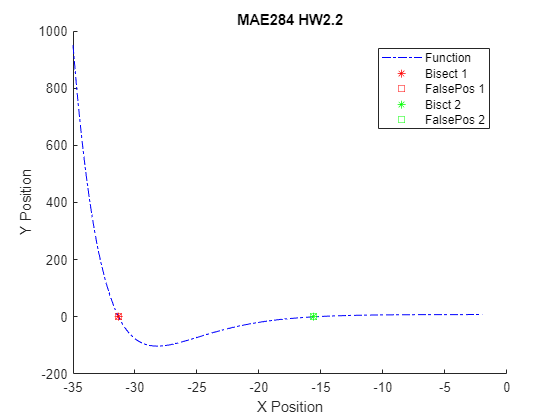

plot(xrb, f(xrb), "r*", xrfp, f(xrfp), "rs", xrb2, f(xrb2), "g*", xrfp2, f(xrfp2), "gs")
legend("Function", "Bisect 1", "FalsePos 1", "Bisct 2", "FalsePos 2", "Location", "best")
hold off

## Problem #3 - Newton-Raphson

**a) Display the vector as a column vector**

format long
x = [.9];
g = @(x) x.^3 + 2*x +34;
dg = @(x) 3*x.^2 + 2;

for i = 1:9
    x(i+1) = x(i)- (g(x(i))/dg(x(i)));
end

disp(x')

   0.900000000000000
  -7.345823927765236
  -5.044915901549569
  -3.711359168885046
  -3.144825871980325
  -3.037728262027065
  -3.034124086846070
  -3.034120091462843
  -3.034120091457937
  -3.034120091457937



**b) Calculate the exact real root using the roots function.  **

p = [1 0 2 34];
r = roots(p)

r =   1.517060045728969 + 2.984026398516197i
  1.517060045728969 - 2.984026398516197i
 -3.034120091457936 + 0.000000000000000i


r_real = r(r==real(r));
fprintf("The exact root of the function is %.10f", r_real)

The exact root of the function is -3.0341200915

**c) Why does the Newton-Raphson method initially overshoot the exact value and then increase (or decrease) to converge to the exact value?**

Because the Netwon method uses the slope of the problem at the point, therefore if the slope not similar to the slope at the root, then the initial estimate will be far off, and it will slowly work its way closer and closer to the actual root.

## Problem #4 - Baseball trajectory

**a) Plot the function**

**b) Will the catcher catch the ball?  **

**c) Compute the maximum height reached**

**    i) Golden section search**

**    ii) Parabolic interpolation**

**    iii) MATLAB's fminbnd**

## Problem #5 - 2D Optimization

c = @(x,y) (7.3-.02*x-.38*y)

**a) 3D plot of function**

**b) 1st initial guess, find maximum, display in fprintf**

**c) plot maximum on plot from part a)**

**d) 2nd initial guess, find max and add to plot from part a)**

**e) What changes between the two different initial guesses and why?**

ANSWER HERE

## Helper functions

### Bisect function

function[xr, i, fx, ea] = bisect(f, xL, xu, et)
%bisect: bisection root locator that finds roots between XL and xu
% Inputs: 
% f - function to be evaluated
% xL, xu - lower and upper bounds, respectively
% et - maximum allowable error (default 0.0001%)
% Outputs:
% xr - estimated root location
% fx - input function value at the estimated root location
% ea - magnitude of approximate relative error (%)

% Created by: Isheeta Ranade
% 22 January, 2018

if nargin<3, error('At least 3 input arguments required'), end % Check to ensure 3 inputs are included
test = f(xL)*f(xu); % Create a variable test which is used to see if the sign changes between xL and xu.
if test > 0, error('No sign change f(xL) and f(xu)'), end
if nargin < 4 | isempty(et), et=0.0001; end % Ensure et is specified

xr = xL;
ea = 100; 
for i = 1:50
    xrold = xr;
    xr = (xL + xu)/2;
   sgnchng = f(xL)*f(xr);
   if sgnchng < 0
       xu = xr;
       ea = abs((xr-xrold)/xr)*100;
   elseif sgnchng > 0
       xL = xr;
       ea = abs((xr-xrold)/xr)*100;
   else
       ea = 0;
   end
       if ea < et
           break
       end
end % end of for loop
 fx = f(xr);      
end

### False position function

function[xr, i, fx, ea] = falsePos(f, xL, xu, et)
%bisect: bisection root locator that finds roots between XL and xu
% Inputs: 
% f - function to be evaluated
% xL, xu - lower and upper bounds, respectively
% et - maximum allowable error (default 0.0001%)
% Outputs:
% xr - estimated root location
% fx - input function value at the estimated root location
% ea - magnitude of approximate relative error (%)

% Created by: Isheeta Ranade
% 22 January, 2018

% Modified by: Jackson Lee
% 7 February, 2023

if nargin<3, error('At least 3 input arguments required'), end % Check to ensure 3 inputs are included
test = f(xL)*f(xu); % Create a variable test which is used to see if the sign changes between xL and xu.
if test > 0, error('No sign change f(xL) and f(xu)'), end
if nargin < 4 | isempty(et), et=0.0001; end % Ensure et is specified

xr = xL;
ea = 100; 
for i = 1:500
    xrold = xr;
    xr = xu - ((f(xu)*(xL-xu))/(f(xL)-f(xu)));  %Changes for False Position
   sgnchng = f(xL)*f(xr);
   if sgnchng < 0
       xu = xr;
       ea = abs((xr-xrold)/xr)*100;
   elseif sgnchng > 0
       xL = xr;
       ea = abs((xr-xrold)/xr)*100;
   else
       ea = 0;
   end
       if ea < et
           break
       end
end % end of for loop
 fx = f(xr);      
end

### Golden-section search function

### Parabolic interpolation function

function [xmin,fmin,ea,iter] = paramin(f,xL,xu,xm,es,maxIt,varargin)
% paramin: minimization using parabolic interpolation
%   [xmin,fmin,ea,iter] = paramin(f,xL,xu,es,maxIt,p1,p2,...)
% Inputs:
%   f = function to be evaluated
%   xL, xu = lower and upper bounds, respectively
%   xm = first guess at minimum (default (xL+xu)/2)
%   es = allowable relative error (default = 0.0001%)
%   maxIt = maximum allowable iterations (default = 50)
% Outputs:
%   xmin = location of minimum
%   fmin = minimum function value
%   ea   = magnitude of approximate relative error (%)
%   iter = number of iterations required to find the minimum

% Created by: Isheeta Ranade
% Edited by: Kim Xu
% Today's date: 9/14/2021

if nargin<3, error('At least 3 input arguments required'), end
if nargin<4||isempty(xm), xm=(xL+xu)/2; end
if nargin<5||isempty(es), es=0.0001; end
if nargin<6||isempty(maxIt), maxIt=50; end


iter = 0;
x4 = xu;
while(1)
    xold = x4;
    iter = iter + 1;
    x4 = xm - 0.5*((xm-xL)^2*(f(xm)-f(xu))-(xm-xu)^2*(f(xm)-f(xL)))/...
        ((xm-xL)*(f(xm)-f(xu))-(xm-xu)*(f(xm)-f(xL)));
    if x4 <= xu
        xL = xm;
        xm = x4;
    else
        xu = xm;
        xm = x4;
    end
    
    if x4 ~= 0
        ea = abs((x4 - xold)/x4)*100;
    end
    if ea <= es || iter >= maxIt, break, end
         
end
xmin = x4;
fmin = f(x4);
end